% Define the power law function
function y = power_law(W, a, c)
    y = a * power(W, c);
end

% Updated example data
weights = [44.145, 98.1, 88.29, 83.385, 78.48, 93.195];  % W
lengths = [0.66, 0.8, 1.7, 1.2, 0.91, 0.95];  % L

% Fit the power law curve to the data
p0 = [1, 1];  % Initial guess for parameters
options = optimset('Display','off');  % Suppress display
[popt, ~, ~, exitflag] = lsqcurvefit(@(params, W) power_law(W, params(1), params(2)), p0, weights, lengths, [], [], options);

% Extract the fitted parameters
a_fit = popt(1);
c_fit = popt(2);

% Print the fitted parameters
disp(['Fitted parameter a: ', num2str(a_fit)]);

Fitted parameter a: 0.097577


disp(['Fitted parameter c: ', num2str(c_fit)]);

Fitted parameter c: 0.53969


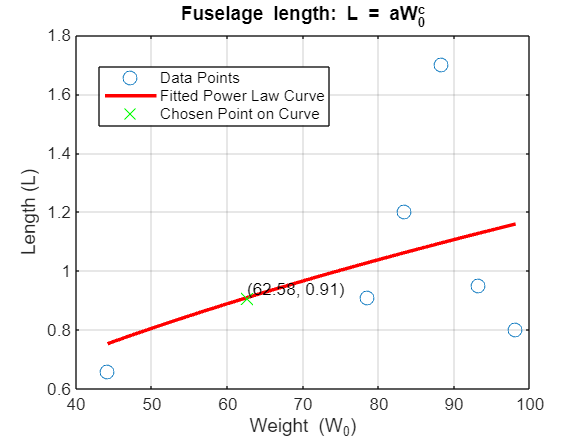


% Generate points on the fitted curve for plotting
weights_curve = linspace(min(weights), max(weights), 100);
lengths_curve = power_law(weights_curve, a_fit, c_fit);

% Plot the data points and the fitted curve
figure;
plot(weights, lengths, 'o', 'MarkerSize', 8, 'DisplayName', 'Data Points');
hold on;
plot(weights_curve, lengths_curve, 'r', 'LineWidth', 2, 'DisplayName', 'Fitted Power Law Curve');
xlabel('Weight (W_0)');
ylabel('Length (L)');
title('Fuselage length: L = aW_0^c');
legend('Location', 'best');

% Choose a point on the curve
chosen_weight = 62.58;  
chosen_index = find(weights_curve < chosen_weight, 1, 'last');
chosen_length = lengths_curve(chosen_index);
plot(chosen_weight, chosen_length, 'gx', 'MarkerSize', 10, 'DisplayName', 'Chosen Point on Curve');
text(chosen_weight, chosen_length, ['(', num2str(chosen_weight, '%.2f'), ', ', num2str(chosen_length, '%.2f'), ')'], 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
grid on;
legend('Location', 'best');
hold off;